# This routine is intended at analyzing Cp data acquired with our DR used in the Dynacool PPMS of the Lee lab

## To do:

- Add error bars

For dT data, use the percent temperature increase + standard deviation

For dCp values, add the SampHCErrmJmoleK field 

- Normalize with respect to molar mass

## Import data

Data = ImportCpDR('2018-07-31_TmVO4-LS5228-DR-HC180731.dat');

## Assign variable names and get rid of NaN rows

T = [Data.SampleTempKelvin];
Data(any(isnan(T), 2), :) = [];% Remove rows where T is NaN
H = [Data.FieldOersted];

## Separate data according to value of field

[uh,~,X] = unique(round(H));
split = accumarray(X,1:size(Data,1),[],@(r){Data(r,:)});
M = 283.87;% Molar mass of TmVO4, in g/mol
m = 1e-3;% mass in g
for i=1:length(split)
    split{i}.Properties.VariableNames{'SampleTempKelvin'} = 'T';% rename the temperature column
    split{i}.Properties.VariableNames{'SampHCJK'} = 'Cp';% rename the heat capacity column
    split{i}.Cpmol = split{i}.Cp *1e-6*M/m;% molar heat capacity, in J/mol/K
end

## Plot the full dataset

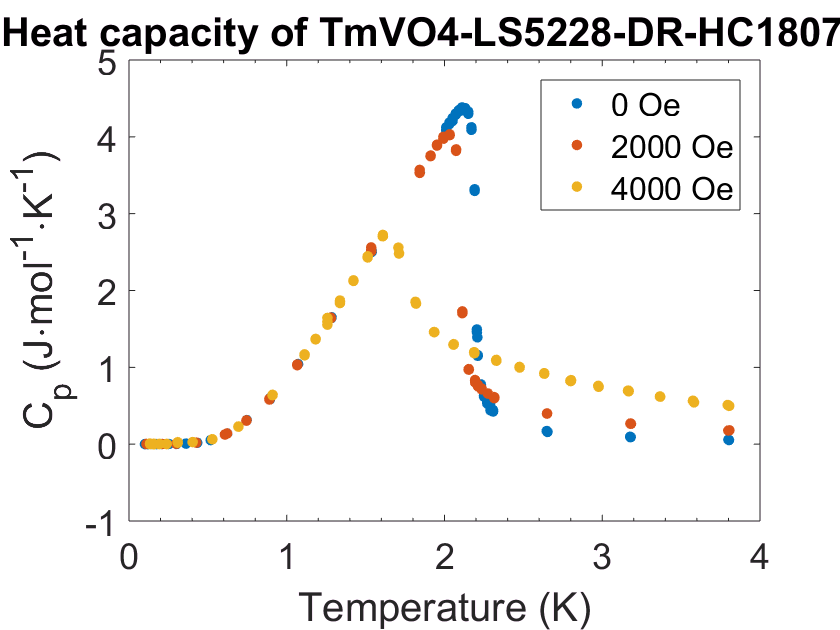

close 
figure
for i=1:length(split)
    plot(split{i}.T,split{i}.Cpmol,'.','MarkerSize',18,'DisplayName',[num2str(uh(i)),' Oe'])
    hold on
end
xlabel('Temperature (K)')
ylabel('C_p (J\cdotmol^{-1}\cdotK^{-1})')
title('Heat capacity of TmVO4-LS5228-DR-HC180731')
legend('show')

## How to fit the data

Since gamma depends on T self-consistently and Cp depends on both gamma and T, the only way to fit the data is to:

- Determine gamma numerically from T

- Fit Cp as a function of gamma and T

Edit 2018-10-03: the above suggestion does not work because Matlab can only take one argument for a 1D curve. Solution: since T is an analytical function of gamma (even though gamma is not an anlytical function of T), fit Cp as a function of gamma. Then, use the extracted fitting parameters to plot Cp vs T (not a fit though).

## Initialize data set to fit

clear T; clear Cp; clear dT
maxT = 2.1;% at 0T, for temperatures below maxT, heat capacity looks mean-field
T = split{1}.T(split{1}.T<maxT);% split{1} is the data at 0T
Cp = split{1}.Cpmol(split{1}.T<maxT);

## Determine the total pseudospin gamma

gamma = 0.2*ones(length(T),1);% initialize pseudospin array
% Tred = @(x,t) 2.2*2*x./atanh(2*x)-t;% Tred = T_calculated - T_measured
x0 = [10^-15 0.5];% range of the pseudospin
g = @(t) fzero(@(x) 2.2*2*x./atanh(2*x)-t,x0);% total pseudospin as a function of temperature t
% results from identifying the abscissa of the zero of 
% the anonymous function passed as argument of the fzero function

The expression of the anonymous function inside fzero is that of a reduced temperature defined as T_caluclated - T_measured, such that it takes the value zero when T_calculated = T_measured. This expression results from inverting the self-consistent equation 2*gamma = th(beta*gamma/2), where gamma is the total pseudospin and beta is the inverse temperature beta = 1/(k_B*T). Therefore, when the function takes the value zero, the correponding abscissa is the value of the total pseudospin at the measured temperature.

Note: the equation 2*gamma = th(beta*gamma/2) is for a reduced beta = beta/beta_c such that k_B*T_c/J_0 = 1/4. In order to get the actual value of the critical temperature, one needs to multiply k_B*T by 4*T_c. The factor 2 in the numerator of the function results from the multiplication by 4 and the factor 2.2 is the actual value of T_c (for this particular sample).

for j = 1:length(gamma)
    gamma(j) = g(T(j));
end

Note: to check the validity of the result, calculate T(gamma) for the calculated gamma, and take the difference with the original value of T. The result should be less than 1% off, ideally less than 1/1000. 

## Plot reduced temperature of the last data point as a function of gamma

Just to show what is going on in the above code

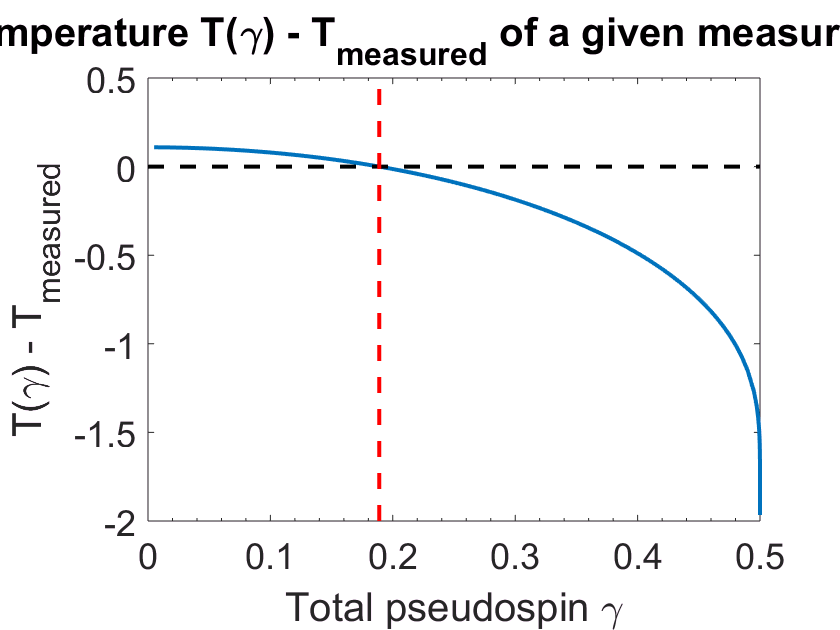

Tred = @(x) 2.2*2*x./atanh(2*x) - T(j);% Reduced temperature at temperature T(j)
% Tred is the same function as the anonymous function passed as argument of fzero
% in the definition of g, taken at a temperature T(j)
figure 
rev_x = [logspace(-15,-2),0.01:0.01:0.99];
x = 0.5.*(1-rev_x);% pseudospin values, with log scale close to Sz,max=0.5
plot(x,Tred(x))% plot Tred vs gamma; 
% the above code uses fzero to extract the value of gamma for which Tred = 0 
% i.e. T_calculated = T_measured
hold on
y = 0;
line(xlim,[y,y],'Color','black','LineStyle','--')% plot a horizontal line at y=0 
% and span it to the current figure's x limits
g0 = gamma(j);
line([g0,g0],ylim,'Color','red','LineStyle','--')% plot a vertical line at x=gamma(j)=g(T(j))
% and span it to the current figure's y limits
xlabel('Total pseudospin \gamma')
ylabel('T(\gamma) - T_{measured}')
title('Reduced temperature T(\gamma) - T_{measured} of a given measured temperature')

## Plot gamma

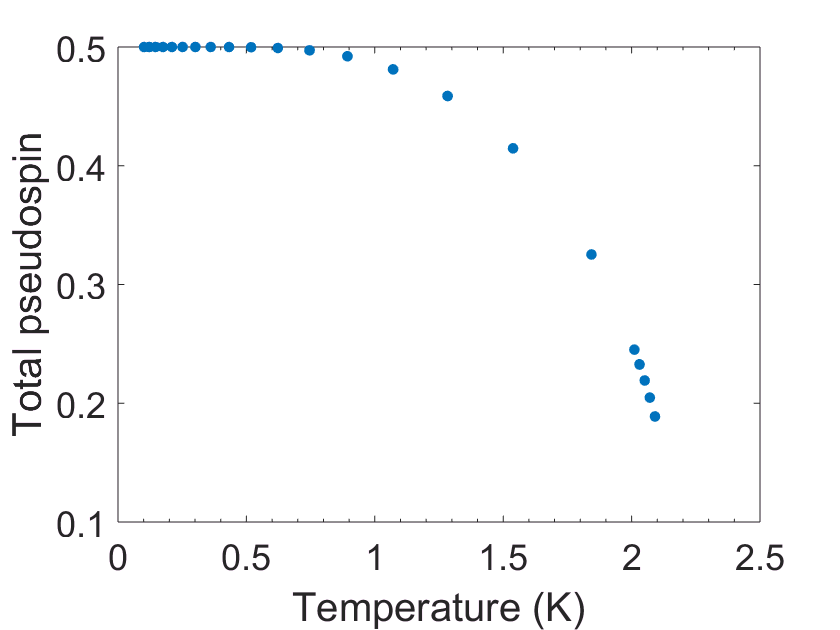

figure 
plot(T,gamma,'.')
xlabel('Temperature (K)')
ylabel('Total pseudospin')

## Fit the data at 0T

The expression of Cp(gamma) is:

a*(atanh(2*x))^2*(sech(atanh(2*x)))^2/(1-(sech(atanh(2*x)))^2*atanh(2*x)/(2*x))

or, since (sech(X))^2 = 1 - (tanh(X))^2:

a*(atanh(2*x))^2*(1-4*x^2)/(1-(1-4*x^2)*atanh(2*x)/(2*x))

where x = gamma

See function fitCpvsPseudospin.m

fitCp0T =      General model:
     fitCp0T(x) = A*(atanh(2*x))^2*(1-4*x^2)/(1-(1-4*x^2)*atanh(2*x)/(2*x))
     Coefficients (with 95% confidence bounds):
       A =       3.157  (3.151, 3.163)

gof0T = struct with fields:
           sse: 0.0197
       rsquare: 0.9999
           dfe: 65
    adjrsquare: 0.9999
          rmse: 0.0174


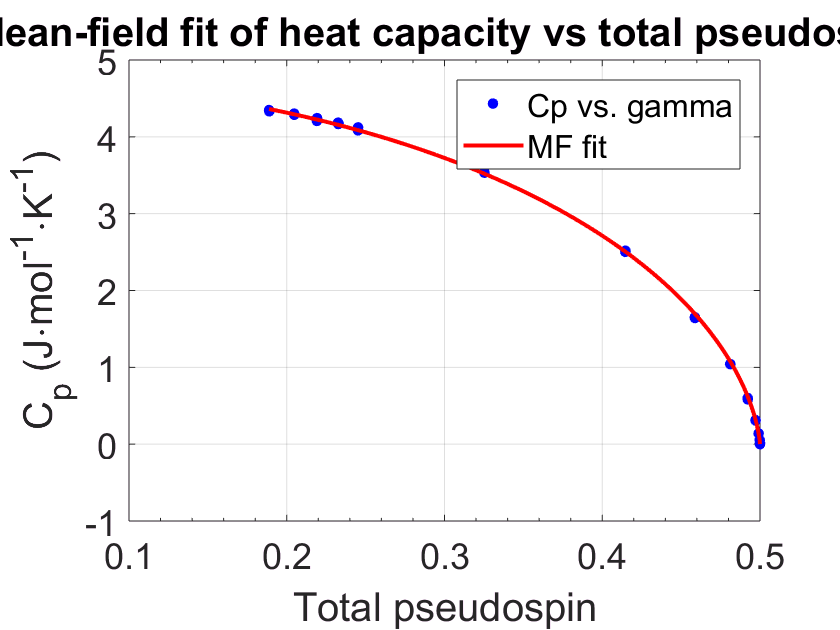

X = gamma./T;% the variable that appears in the expression of heat capacity is a ratio of pseudospin to temperature
[fitCp0T, gof0T] = fitCpvsPseudospin(gamma,Cp,'C_p (J\cdotmol^{-1}\cdotK^{-1})')

% The third argument of the fitting function is an optional argument
% that defines the label of the y axis of the plot

# Average data

## Test the temperature scattering between data points supposedly taken at the "same" temperature

4mK is the empirical maximal dispersion of data points taken consecutively at a given temperature. In order to check this, one can run the following code on the temperature variable T:

nrep = 3;% number of repetitions of the measurement at each temperature
% We want to compute the temperature separation between two data points
% that are NOT repetitions of the same measurement
Tsep = 4e-3;% value of temperature separation to be tested, in Kelvin
% Data points taken within an interval of Tsep are considered to be measured at the same temperature setpoint
for i = 1
    for k = 1:length(split{i}.T)-nrep
        if abs(split{i}.T(k+nrep)-split{i}.T(k))<Tsep
% if the values of temperature for two data points supposedly
% measured at two different temperature setpoints are separated by less than Tsep
            split{i}.T(k)% display the value of temperature for the first data point
        end
    end
end

If this piece of code outputs one or more values, that means that at least two different measurements were separated by less than Tsep. In this case, reduce Tsep in order to reach a value for which the code does not output anything.

## Compute average of data points taken

L = length(split);
for i = 1
    Tm = [];Cpm = [];stdCpm = [];
    for k = 1:3:length(split{i}.T)
        ind = [k];
        for j = k+1:k+4
            if abs(split{i}.T(j)-split{i}.T(k))<Tsep
                ind = [ind, j];
            end
            if j>= length(split{i}.T)
                break
            end
        end
        Tm = [Tm,mean(split{i}.T(ind))];% average of temperature for data points
%         taken at the same temperature setpoint
        Cpm = [Cpm,mean(split{i}.Cpmol(ind))];% average of heat capacity
        stdCpm = [stdCpm,std(split{i}.Cpmol(ind))];% standard deviation of heat capacity
    end
    avgData(i).T = Tm;
    avgData(i).Cp = Cpm;
    avgData(i).stdCp = stdCpm;
end

## Plot averaged data

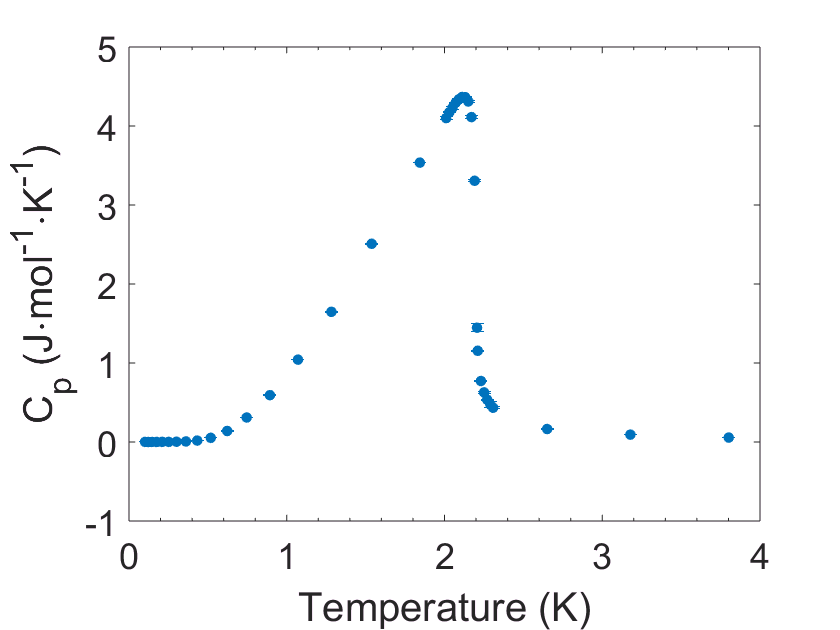

figure
hold on
% cntr = 0;
% Lm = round(L./3,0);
for i = 1
    errorbar(avgData(i).T,avgData(i).Cp,avgData(i).stdCp,'.','MarkerSize',18)
%     cntr = cntr+i;
end
% vline(1.55,'b:','1.55')
% vline(0.7,'r:','0.7')
% ylim([0 4])
xlabel('Temperature (K)')
ylabel('C_p (J\cdotmol^{-1}\cdotK^{-1})')

% hleg = legend('0.11','0.22','0.32');
% title(hleg,'x')
% title('Heat capacity of Tm_{1-x}Y_xVO4')

# Fit averaged data

## Determine the total pseudospin gamma for the averaged data

Only include temperatures below the transition temperature

avgData(1).Tord = avgData(1).T(avgData(1).T<maxT);
avgData(1).gamma = 0.2*ones(1,length(avgData(1).Tord));% initialize pseudospin array
% Tred = @(x,t) 2.2*2*x./atanh(2*x)-t;% Tred = T_calculated - T_measured
disp(['x0 = [',string(x0),']'])% range of the pseudospin

    "x0 = ["    "1e-15"    "0.5"    "]"



g = @(t) fzero(@(x) 2.2*2*x./atanh(2*x)-t,x0);% total pseudospin as a function of temperature t
% results from identifying the abscissa of the zero of 
% the anonymous function passed as argument of the fzero function
% see calculation made above for the non averaged data for more explanation
for jj = 1:length(avgData(1).gamma)
    avgData(1).gamma(jj) = g(avgData(1).Tord(jj));
end

## Plot gamma  for the averaged data

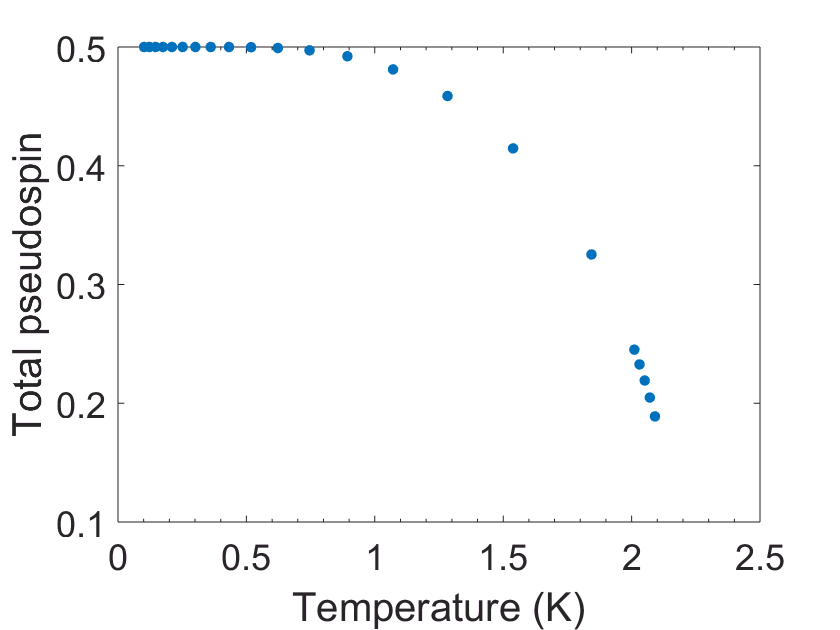

figure 
plot(avgData(1).Tord,avgData(1).gamma,'.')
xlabel('Temperature (K)')
ylabel('Total pseudospin')

## Fit the data at 0T

See function fitCpvsPseudospin.m

avgData = struct with fields:
          T: [1×37 double]
         Cp: [1×37 double]
      stdCp: [1×37 double]
       Tord: [1.8437 1.5384 1.2832 1.0711 0.8934 0.7459 0.6224 0.5183 0.4324 0.3610 0.3014 0.2515 0.2100 0.1751 0.1462 0.1220 0.1017 2.0107 2.0308 2.0510 2.0710 2.0910]
      gamma: [0.3253 0.4147 0.4587 0.4812 0.4922 0.4972 0.4991 0.4998 0.5000 0.5000 0.5000 0.5000 0.5000 0.5000 0.5000 0.5000 0.5000 0.2452 0.2327 0.2192 0.2048 0.1889]
      Cpord: [3.5362 2.5090 1.6476 1.0423 0.5927 0.3105 0.1396 0.0528 0.0182 0.0067 0.0032 0.0020 0.0013 7.7265e-04 7.2148e-04 2.0633e-04 0.0013 4.1001 4.1740 4.2312 4.2956 4.3380]
    fitCp0T: [1×1 cfit]
      gof0T: [1×1 struct]


avgData = struct with fields:
          T: [1×37 double]
         Cp: [1×37 double]
      stdCp: [1×37 double]
       Tord: [1.8437 1.5384 1.2832 1.0711 0.8934 0.7459 0.6224 0.5183 0.4324 0.3610 0.3014 0.2515 0.2100 0.1751 0.1462 0.1220 0.1017 2.0107 2.0308 2.0510 2.0710 2.0910]
      gamma: [0.3253 0.4147 0.4587 0.4812 0.4922 0.4972 0.4991 0.4998 0.5000 0.5000 0.5000 0.5000 0.5000 0.5000 0.5000 0.5000 0.5000 0.2452 0.2327 0.2192 0.2048 0.1889]
      Cpord: [3.5362 2.5090 1.6476 1.0423 0.5927 0.3105 0.1396 0.0528 0.0182 0.0067 0.0032 0.0020 0.0013 7.7265e-04 7.2148e-04 2.0633e-04 0.0013 4.1001 4.1740 4.2312 4.2956 4.3380]
    fitCp0T: [1×1 cfit]
      gof0T: [1×1 struct]


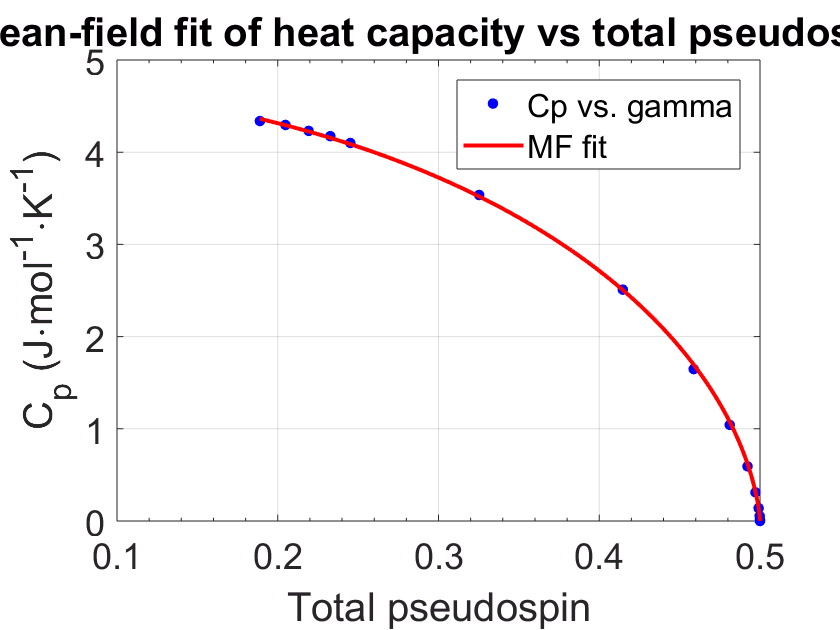

avgData(1).Cpord = avgData(1).Cp(avgData(1).T<maxT);
[fitAvgCp0T, gofAvg0T] = fitCpvsPseudospin(avgData(1).gamma,avgData(1).Cpord,'C_p (J\cdotmol^{-1}\cdotK^{-1})')

% The third argument of the fitting function is an optional argument
% that defines the label of the y axis of the plot

# Temperature derivative of heat capacity

## Sort each dataset by increasing value of temperature

for i = 1
    [avgData(i).T,wo] = sort(avgData(i).T);
    avgData(i).Cp = avgData(i).Cp(wo);
end

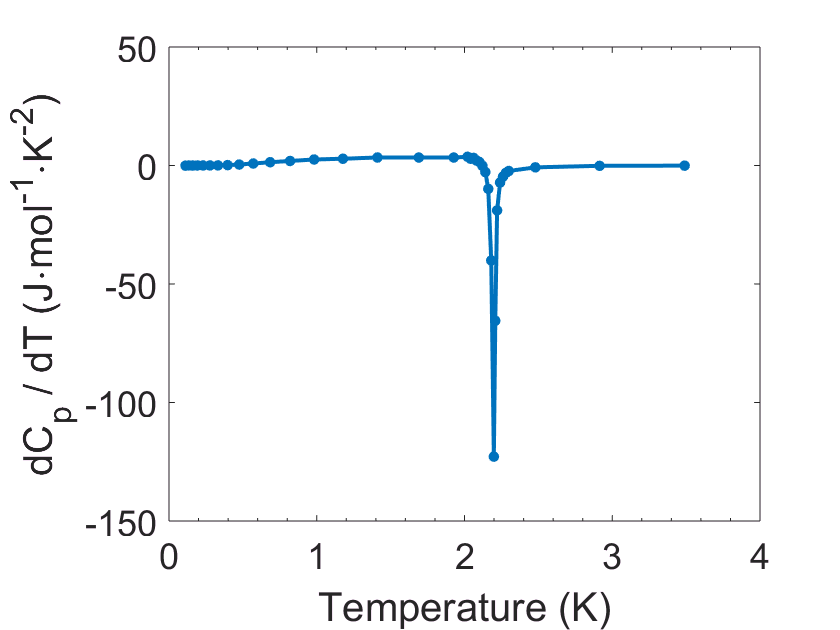

figure
for i = 1
    avgData(i).dCp = diff(avgData(i).Cp)';% differential of Cp
    avgData(i).dT = diff(avgData(i).T');% differential of T
    avgData(i).Tm = mean([avgData(i).T(1:end-1);avgData(i).T(2:end)])';% in order ot have the same # of data points as in dCp
    avgData(i).derCp = avgData(i).dCp ./ avgData(i).dT;% temperature derivative of Cp
    plot(avgData(i).Tm,avgData(i).derCp,'.-')
end
xlabel('Temperature (K)')
ylabel('dC_p / dT (J\cdotmol^{-1}\cdotK^{-2})')